**Multiplicación por Escalar**

%-----APLICANDO LAS PROPIEDADES 
clear all;
close all;
clc;
%-----Gráfica señal original-----
Fs=100;
t=-1:1/Fs:2;
L=3000;         %Longitud de la señal 
A=-2

A = -2

s=A*((4/3)*t-2/3);
Y=fft(s,L);     %Aplicando transformada rápida

plot(t,s);
title('Gráfica señal original multiplicada por escalar')
xlabel('Tiempo(t)');
ylabel('x(t)');
grid on
figure

P=abs(Y/Fs);
f=linspace(0,Fs,numel(P));

plot(f,P)
axis ([0 5 0 3])
title('Gráfica transformada rápida')
xlabel('Frecuencia(rad/s)')
ylabel('|X(f)|')
grid on


%-----Multiplicación por escalar
syms t f;       %Variables simbólicas
e=-2

e = -2

xe= e*((4/3)*t-2/3);  %Señal por escalar
ye=int(xe*exp(-1i*2*pi*f*t),t,-1,2) %Transformada de Fourier teórica

$$ye = -\frac{2\,{\mathrm{e}}^{-4\,\pi \,f\,\mathrm{i}}\,\left(1-{\mathrm{e}}^{6\,\pi \,f\,\mathrm{i}}+3\,\pi \,f\,\mathrm{i}+3\,\pi \,f\,{\mathrm{e}}^{6\,\pi \,f\,\mathrm{i}}\,\mathrm{i}\right)}{3\,f^{2}\,\pi^{2}}$$

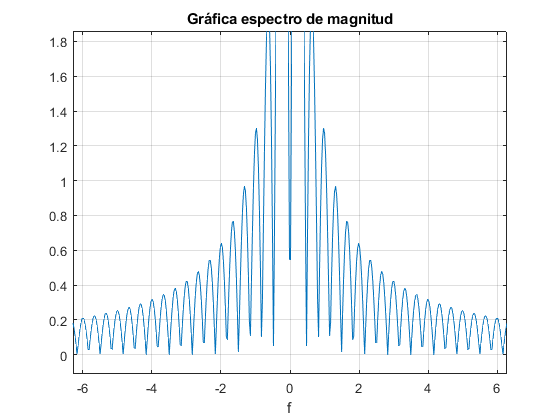

hold on         %sobreposición
fplot(f,abs(ye),[0 5])
legend('FFT','Transformada teórica')
grid on
figure

%-----Gráfica espectro de magnitud
ezplot(abs(ye));
title('Gráfica espectro de magnitud')
grid on

**Cambio de Escala**

%-----Cambio de escala
Fs=100;
A=1/2

A = 0.5000

t=-1/A:1/Fs:2/A;
L=3000;         %Longitud de la señal 
s=((4/3)*t-2/3);%Cambio de escala
Y=fft(s,L);     %Aplicando transformada rápida

plot(t,s);
title('Gráfica cambio de escala')
xlabel('Tiempo(t)');
ylabel('x(t)');
grid on
figure   

P=abs(Y/Fs);
f=linspace(0,Fs,numel(P));

plot(f,P)
axis ([0 5 0 3])
title('Gráfica transformada rápida')
xlabel('Frecuencia(rad/s)')
ylabel('|X(f)|')
grid on

syms t f;       %Variables simbólicas
e=2

e = 2

xce=((4/3)*t-2/3);%Cambio de escala  %
yce=int(xce*exp(-1i*2*pi*f*t),t,-1/e,2/e) %Transformada de Fourier teórica

$$yce = \frac{{\mathrm{e}}^{-2\,\pi \,f\,\mathrm{i}}\,\left(1-{\mathrm{e}}^{3\,\pi \,f\,\mathrm{i}}+\pi \,f\,\mathrm{i}+2\,\pi \,f\,{\mathrm{e}}^{3\,\pi \,f\,\mathrm{i}}\,\mathrm{i}\right)}{3\,f^{2}\,\pi^{2}}$$

hold on         %sobreposición
fplot(f,abs(yce),[0 5])
legend('FFT','Transformada teórica')
grid on
figure


**Traslación en el tiempo**

%-----APLICANDO LAS PROPIEDADES 
clear all;
close all;
clc;

%-----Traslación en el tiempo
Fs=100;
A=4;
t=-1+A:1/Fs:2+A;
L=3000;         %Longitud de la señal 
s=((4/3)*(t-A)-2/3) %Traslación en el t

s =    -2.0000   -1.9867   -1.9733   -1.9600   -1.9467   -1.9333   -1.9200   -1.9067   -1.8933   -1.8800   -1.8667   -1.8533   -1.8400   -1.8267   -1.8133   -1.8000   -1.7867   -1.7733   -1.7600   -1.7467   -1.7333   -1.7200   -1.7067   -1.6933   -1.6800   -1.6667   -1.6533   -1.6400   -1.6267   -1.6133   -1.6000   -1.5867   -1.5733   -1.5600   -1.5467   -1.5333   -1.5200   -1.5067   -1.4933   -1.4800   -1.4667   -1.4533   -1.4400   -1.4267   -1.4133   -1.4000   -1.3867   -1.3733   -1.3600   -1.3467


Y=fft(s,L);     %Aplicando transformada rápida

plot(t,s);
title('Gráfica traslación en el t')
xlabel('Tiempo(t)');
ylabel('x(t)');
grid on
figure   

P=abs(Y/Fs);
f=linspace(0,Fs,numel(P));

plot(f,P)
axis ([0 5 0 3])
title('Gráfica transformada rápida')
xlabel('Frecuencia(rad/s)')
ylabel('|X(f)|')
grid on

syms t f;       %Variables simbólicas
e=3;
xtt=((4/3)*(t-e)-2/3);  %
ytt=int(xtt*exp(-1i*2*pi*f*t),t,-1+e,2+e) %Transformada de Fourier teórica

$$ytt = \frac{{\mathrm{e}}^{-10\,\pi \,f\,\mathrm{i}}\,\left(1-{\mathrm{e}}^{6\,\pi \,f\,\mathrm{i}}+3\,\pi \,f\,\mathrm{i}+3\,\pi \,f\,{\mathrm{e}}^{6\,\pi \,f\,\mathrm{i}}\,\mathrm{i}\right)}{3\,f^{2}\,\pi^{2}}$$

hold on         %sobreposición
fplot(f,abs(ytt),[0 5])
legend('FFT','Transformada teórica')
grid on
figure


%-----Gráfica espectro de magnitud
ezplot(abs(ytt));
title('Gráfica espectro de magnitud')
grid on

**Translación en la Frecuencia**

%-----APLICANDO LAS PROPIEDADES 
clear all;
close all;
clc;
%Traslación en frecuencia
Fs=200;       %Frecuencia de muestreo
t=-1:1/Fs:2;  %Vector de tiempo
L=3000;       %Longitud de la señal 
A=2  ;    %Escalar
s=((4/3)*t-2/3).*(exp(2i*pi*t*A));
Y=fft(s,L);    %Transformada rápida

plot(t,s);

title('Gráfica ')
xlabel('Tiempo(t)');
ylabel('x(t)');
grid on
figure   

P=abs(Y/Fs);
f=linspace(0,Fs,numel(P));

plot(f,P)
axis ([0 5 0 3])
title('Gráfica transformada rápida  y Teórica')
xlabel('Frecuencia(rad/s)')
ylabel('|X(f)|')
grid on


syms t f;       %Variables simbólicas
e=2;
xtf=exp(2*pi*1i*t*e)*((4/3)*t-2/3);
ytf=int(xtf*exp(-1i*2*pi*f*t),t,-1,2); %Transformada de Fourier teórica
hold on         %sobreposición
fplot(f,abs(ytf))
legend('FFT','Transformada teórica')
grid on
figure

%-----Gráfica espectro de magnitud
ezplot(abs(ytf));
title('Gráfica espectro de magnitud- Translación en Frecuencia')
grid on
